clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

desiredSize = [224, 224]; % Set your desired image size

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        
        % Resize or pad the image to the desired size
        resizedImage = imresize(image, desiredSize);
        % Alternatively, use padarray to add padding
        paddedImage = padarray(image, [desiredSize(1)-size(image,1), desiredSize(2)-size(image,2)], 0, 'post');
        
        % Store the resized/padded image and label
        allData = [allData; {resizedImage, categories(i)}];
        
%         allData = [allData; {image, categories(i)}];
    end
end

% define images & labels
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
images = zeros(imageSize(1), imageSize(2), 1, numImages);

for i = 1:numImages
    images(:, :, 1, i) = allData.Image{i};
end

labels = categorical(allData.Label);

% split data into train and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
trainIdx = training(cv);
testIdx = test(cv);
trainImages = images(:, :, :, trainIdx);
trainLabels = labels(trainIdx);
testImages = images(:, :, :, testIdx);
testLabels = labels(testIdx);

% Define the layers of the CNN
layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(numel(categories))
    softmaxLayer
    classificationLayer
    ];

% Training options
options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |        8.59% |       27.48% |       2.9427 |       4.8422 |          0.0100 |
|       3 |          30 |       00:01:11 |       90.62% |       90.99% |       0.2502 |       0.2964 |          0.0100 |
|       5 |          50 |       00:01:41 |       95.31% |              |       0.1092 |              |          0.0100 |
|       6 |          60 |       00:01:56 |       98.44% |       93.24% |       0.0487 |   

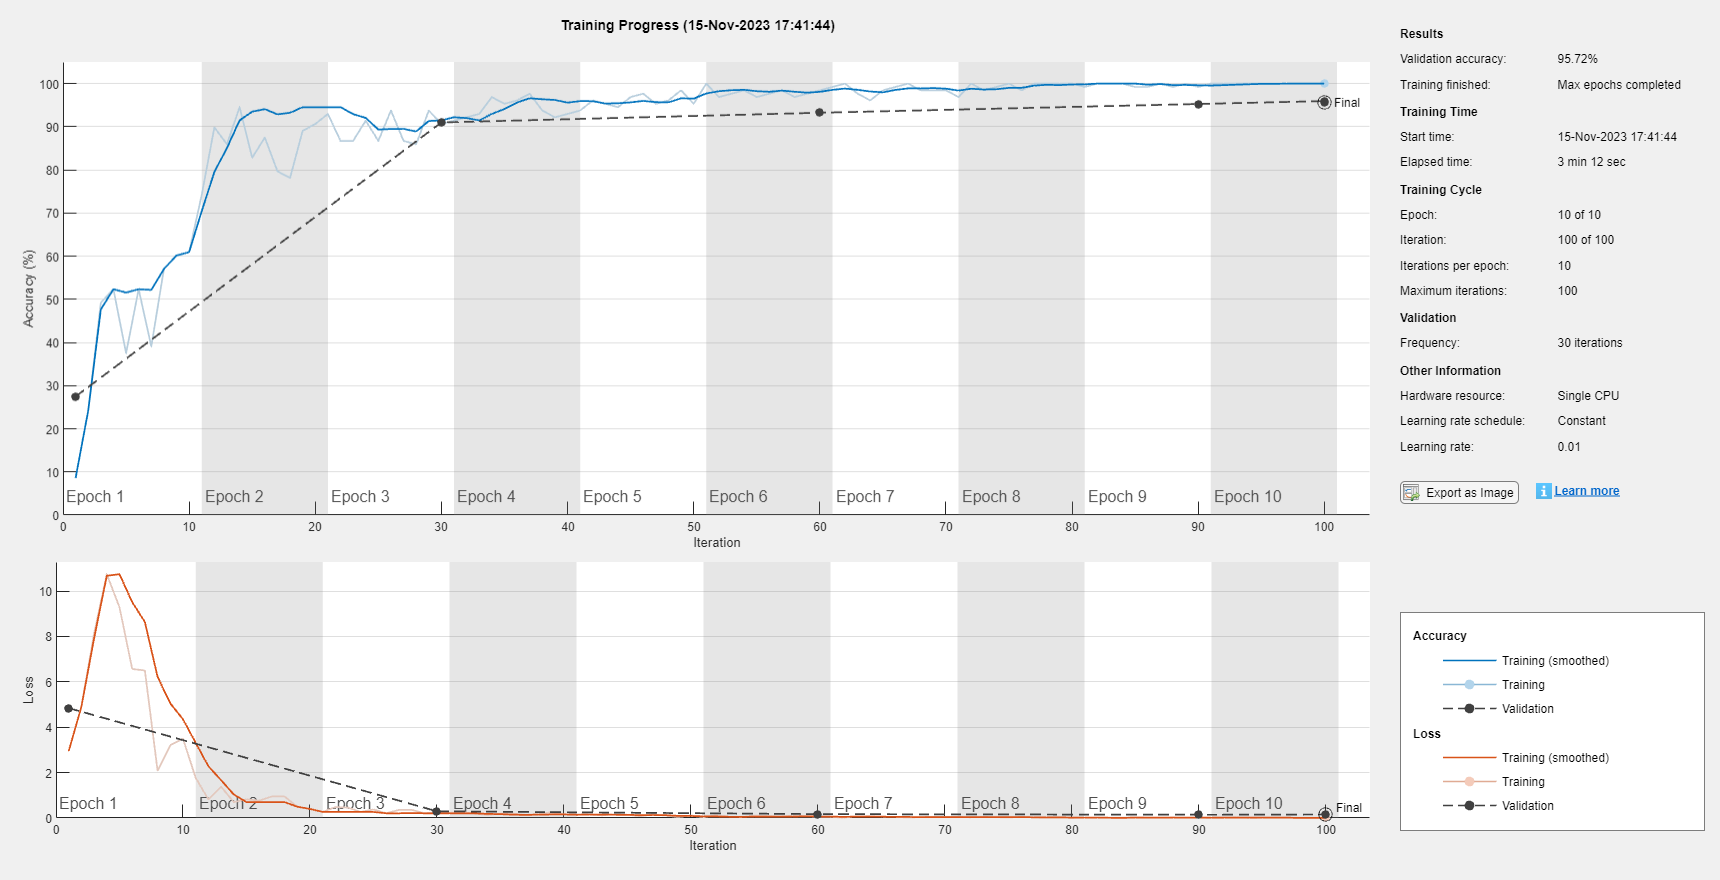

% Train the CNN

trainingStartTime = tic;

% Train the neural network
net = trainNetwork(trainImages, trainLabels, layers, options);


% Stop the timer
trainingTime = toc(trainingStartTime);

% Display the training time
fprintf('Training time: %.2f seconds\n', trainingTime);

Training time: 207.19 seconds


% Classify Test Images
predictedLabels = classify(net, testImages);

% Calculate the Accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 95.72%


% Calculate precision, recall, and F1-score
confusionMatrix = confusionmat(testLabels, predictedLabels)

truePositive = confusionMatrix(1, 1);
falsePositive = confusionMatrix(2, 1);
falseNegative = confusionMatrix(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1Score);

F1-Score: 1.00


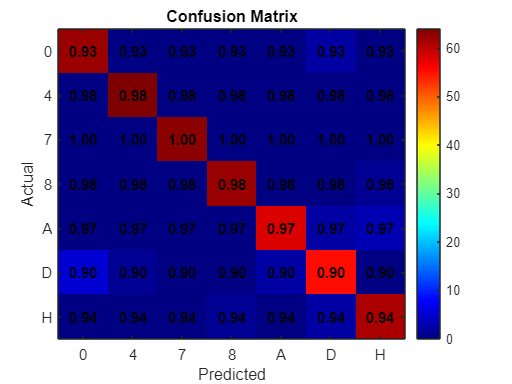

% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix);
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix(i, i) / sum(confusionMatrix(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       19.53% |       14.64% |       2.6636 |       7.9277 |          0.0100 |
|       3 |          30 |       00:01:11 |       92.97% |       91.89% |       0.2247 |       0.2724 |          0.0100 |
|       5 |          50 |       00:01:51 |       96.09% |       94.82% |       0.1038 |       0.1846 |          0.0100 |
|=========================================================================================

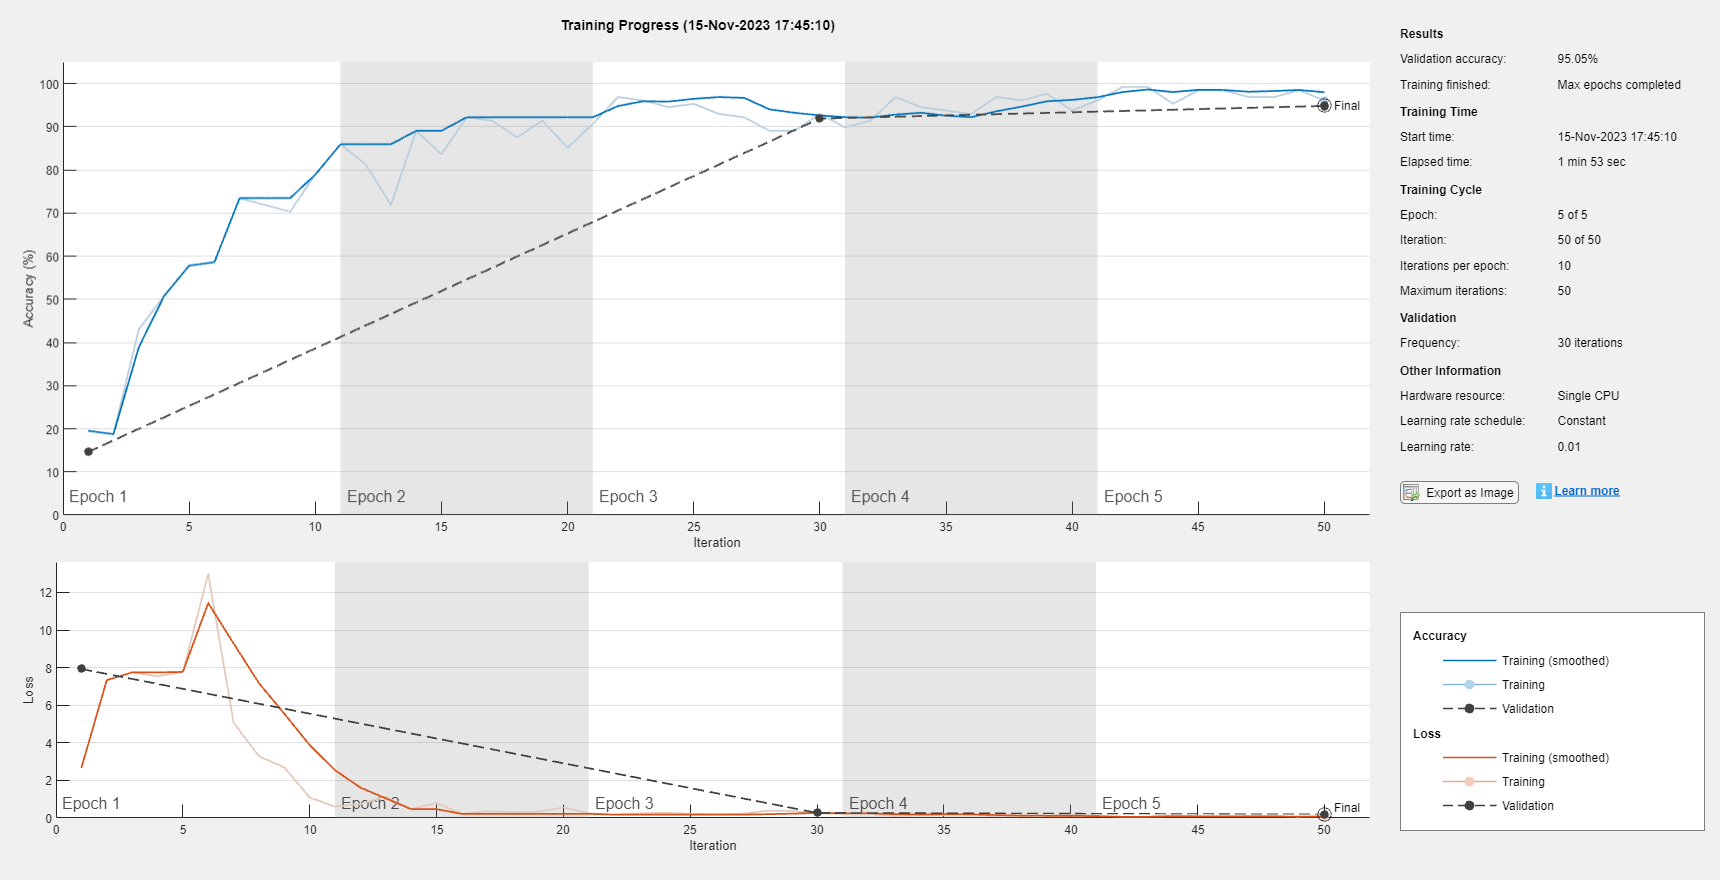

Test Accuracy for 5 Epochs: 95.05%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       12.50% |       29.05% |       2.3620 |       2.3961 |          0.0100 |
|       3 |          30 |       00:01:26 |       89.06% |       90.99% |       0.3025 |       0.2851 |          0.0100 |
|       5 |          50 |       00:02:19 |       98.44% |              |       0.0700 |              |          0.0100 |
|       6 |          60 |       00:02:43 |       98.44% |       95.27% |       0.0448 |   

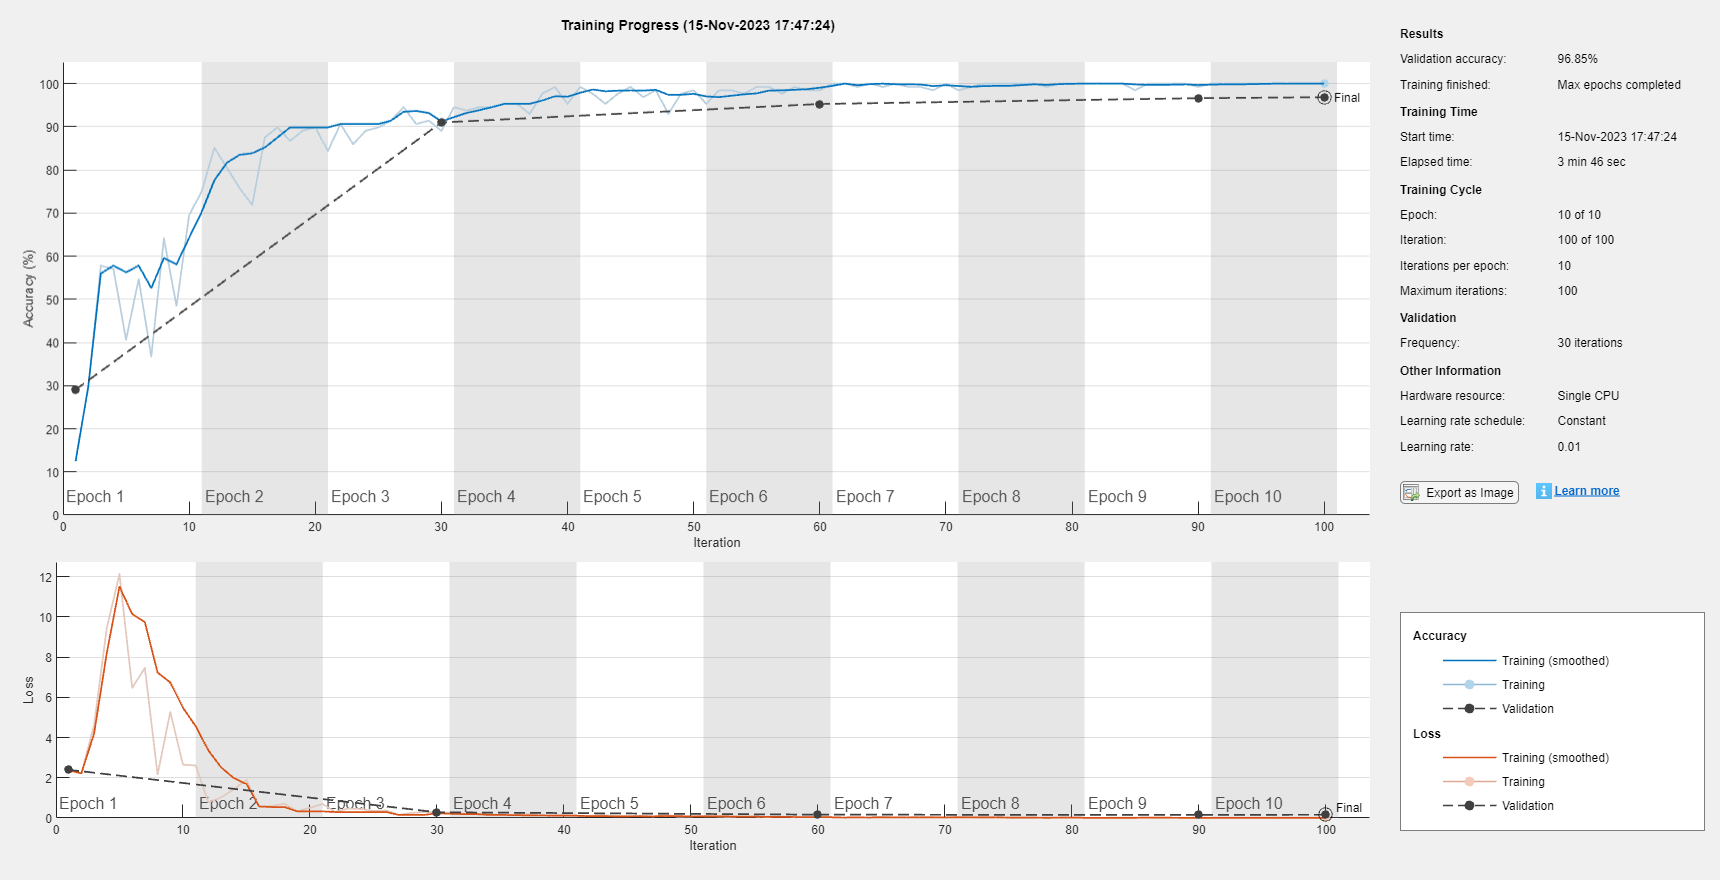

Test Accuracy for 10 Epochs: 96.85%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       12.50% |       33.56% |       2.4843 |       3.8307 |          0.0100 |
|       3 |          30 |       00:01:16 |       97.66% |       93.24% |       0.0991 |       0.2541 |          0.0100 |
|       5 |          50 |       00:02:00 |       96.88% |              |       0.0886 |              |          0.0100 |
|       6 |          60 |       00:02:17 |       98.44% |       95.50% |       0.0396 |   

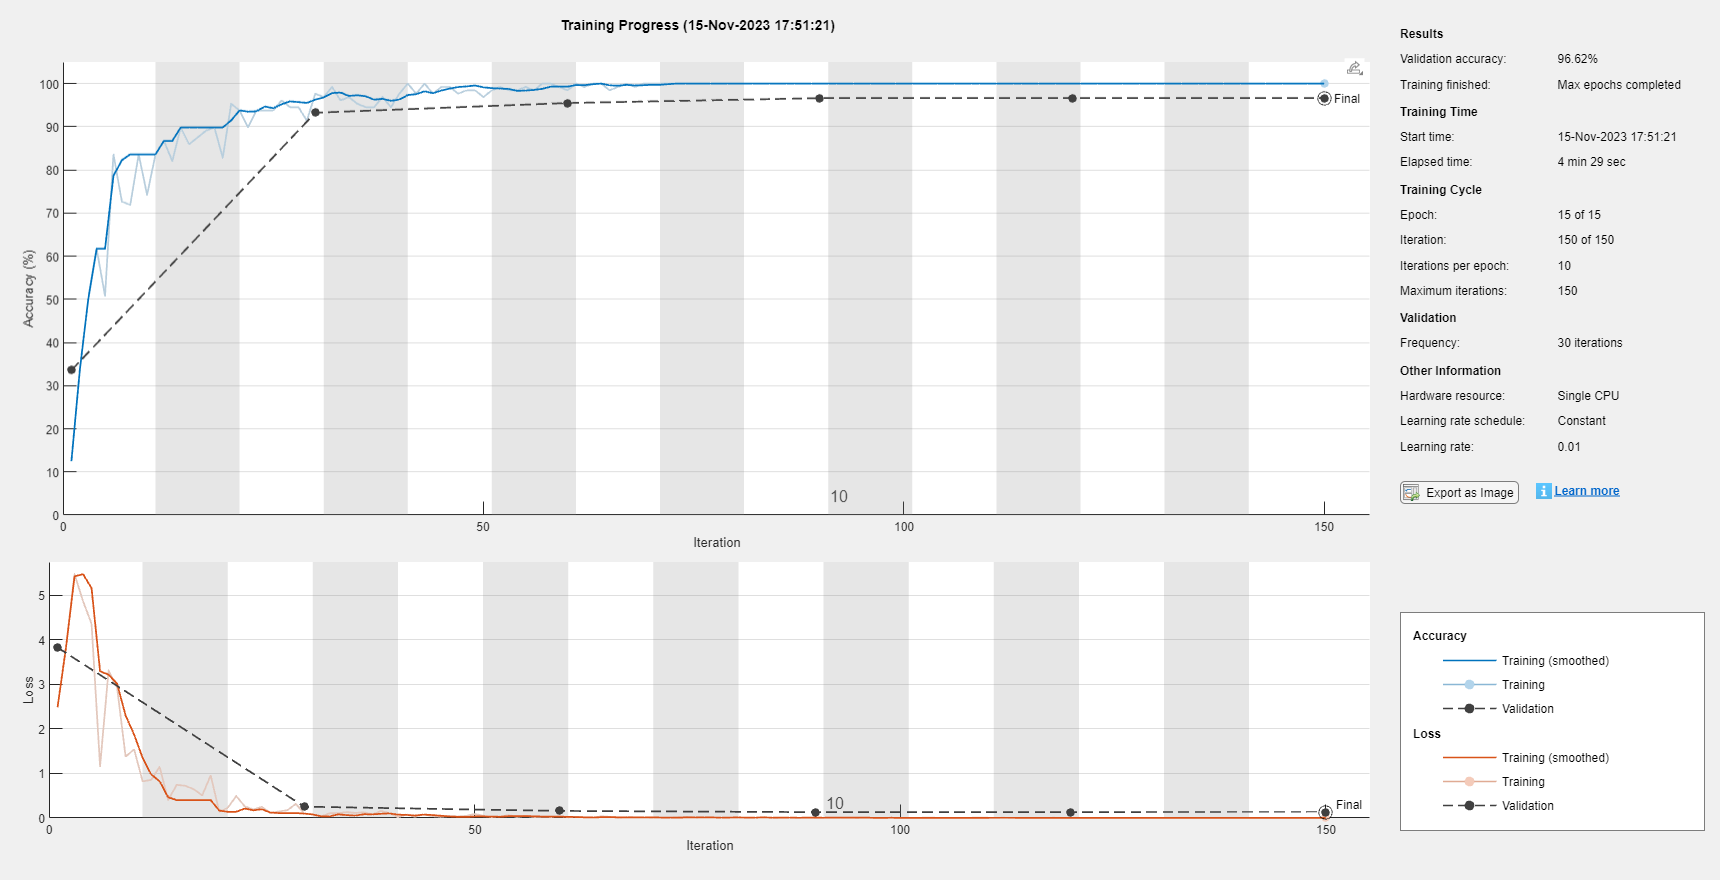

Test Accuracy for 15 Epochs: 96.62%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:27 |       11.72% |       15.99% |       2.8000 |       5.5358 |          0.0100 |
|       3 |          30 |       00:01:46 |       94.53% |       91.22% |       0.1627 |       0.2762 |          0.0100 |
|       5 |          50 |       00:02:16 |       98.44% |              |       0.0804 |              |          0.0100 |
|       6 |          60 |       00:02:32 |       99.22% |       93.92% |       0.0580 |   

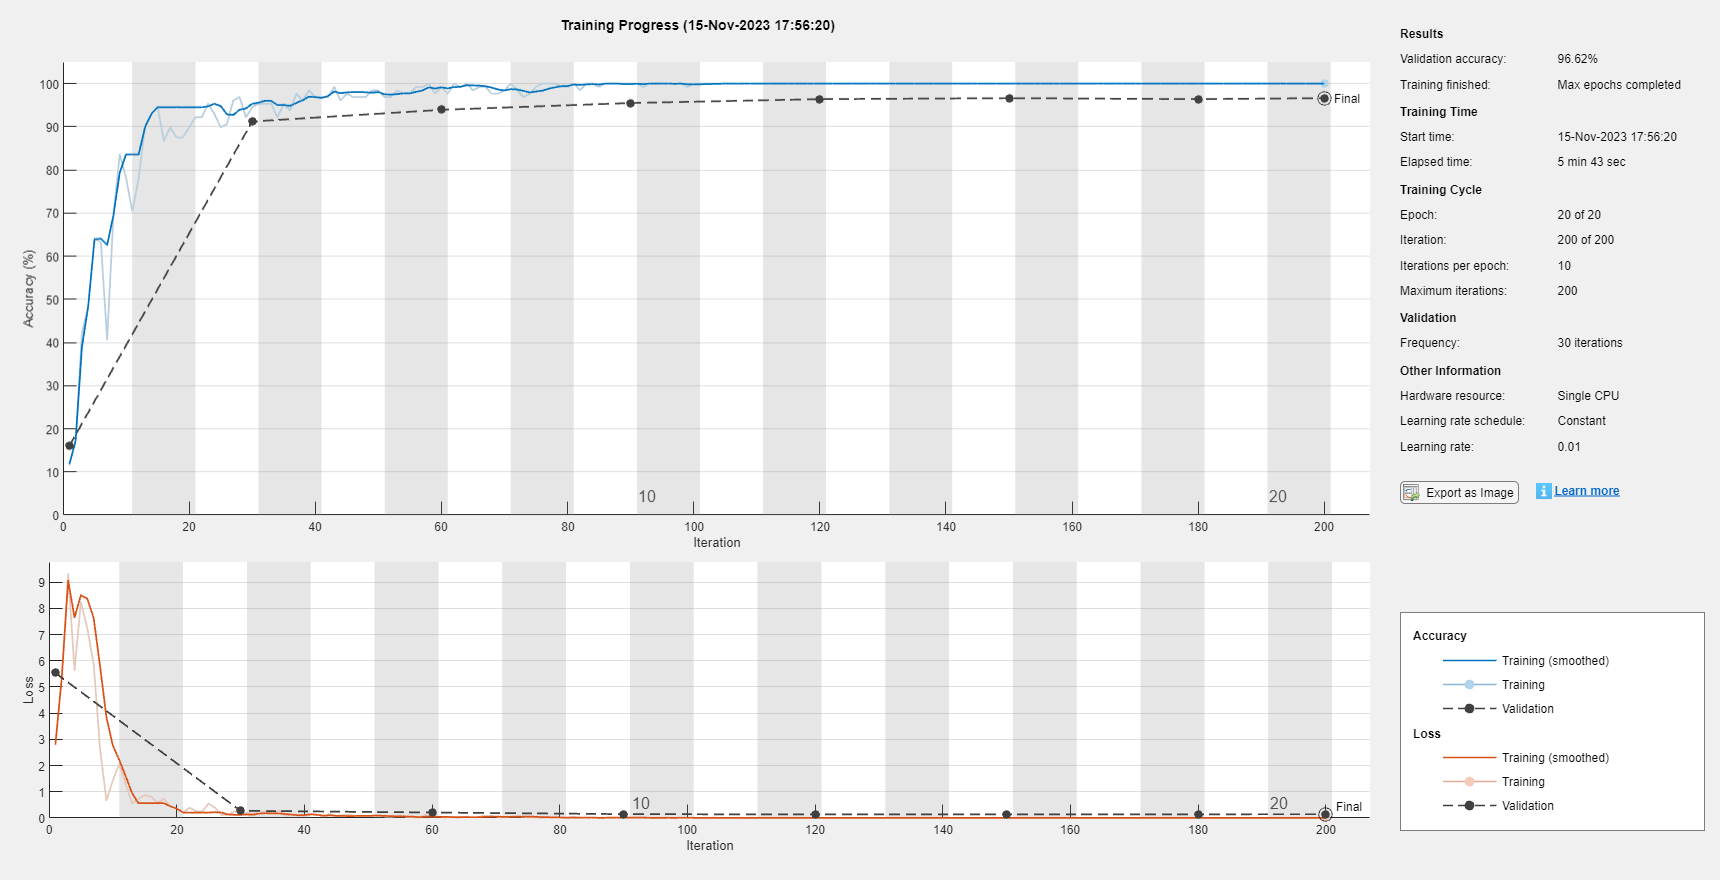

Test Accuracy for 20 Epochs: 96.62%


% Hyperparameter tuning for the number of epochs
numEpochsList = [5, 10, 15, 20]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
EpochsAccuracyMatrix = zeros(length(numEpochsList), 1);
% Initialize a matrix to store training for each number of epochs
EpochsTime = zeros(length(numEpochsList), 1);

for idx = 1:length(numEpochsList)
    currentNumEpochs = numEpochsList(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.MaxEpochs = currentNumEpochs;
    
    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    EpochsAccuracyMatrix(idx) = accuracy;
    EpochsTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Epochs: %.2f%%\n', currentNumEpochs, accuracy * 100);
end

% Plot the accuracy performance
figure;

bar(numEpochsList, EpochsAccuracyMatrix);

ylim([0.9, 1]); 
xlabel('Number of Epochs');
ylabel('Accuracy');
title('Accuracy Performance vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs.eps'

eps_filename = 'results/epochs.eps'

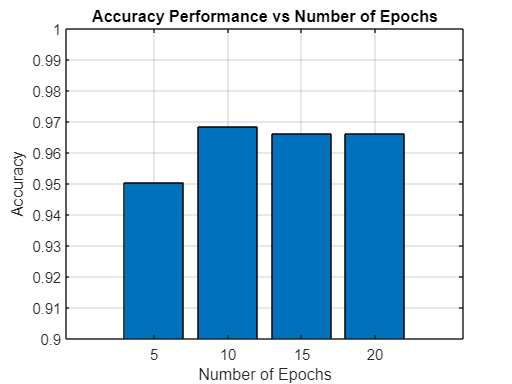

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/epochs.eps


% Plot the training time
figure;

bar(numEpochsList, EpochsTime);

xlabel('Number of Epochs');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs_trainingtime.eps'

eps_filename = 'results/epochs_trainingtime.eps'

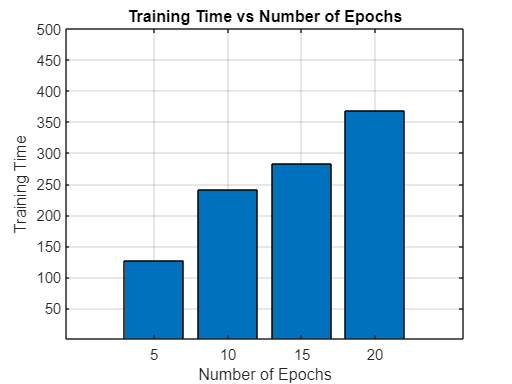

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/epochs_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |        9.38% |       44.14% |       2.6624 |       2.8533 |          0.0100 |
|       3 |          30 |       00:01:00 |       96.88% |       91.44% |       0.0791 |       0.4132 |          0.0100 |
|       5 |          50 |       00:01:38 |       99.22% |              |       0.0176 |              |          0.0100 |
|       6 |          60 |       00:02:05 |       99.22% |       95.05% |       0.0381 |   

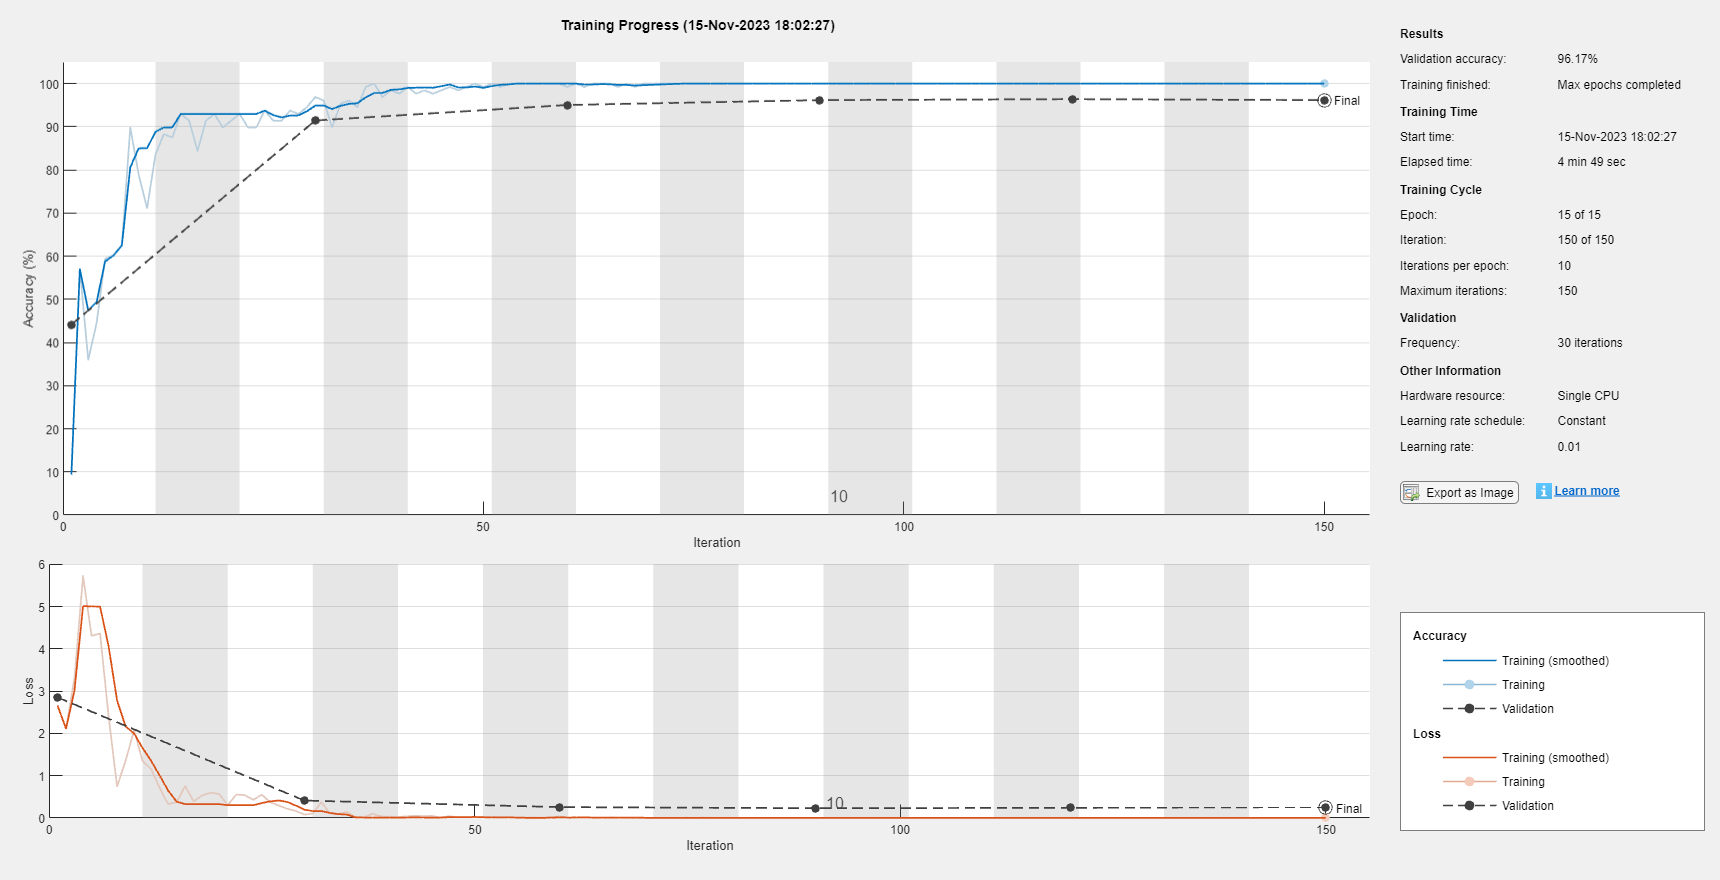

Test Accuracy for 1.000000e-02 Learning Rate: 96.17%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       15.62% |       20.72% |       2.5229 |       2.1195 |          0.0010 |
|       3 |          30 |       00:00:46 |       93.75% |       92.12% |       0.1597 |       0.2530 |          0.0010 |
|       5 |          50 |       00:01:24 |       97.66% |              |       0.0733 |              |          0.0010 |
|       6 |          60 |       00:01:42 |      100.00% |       94.82% |       0.0313 |   

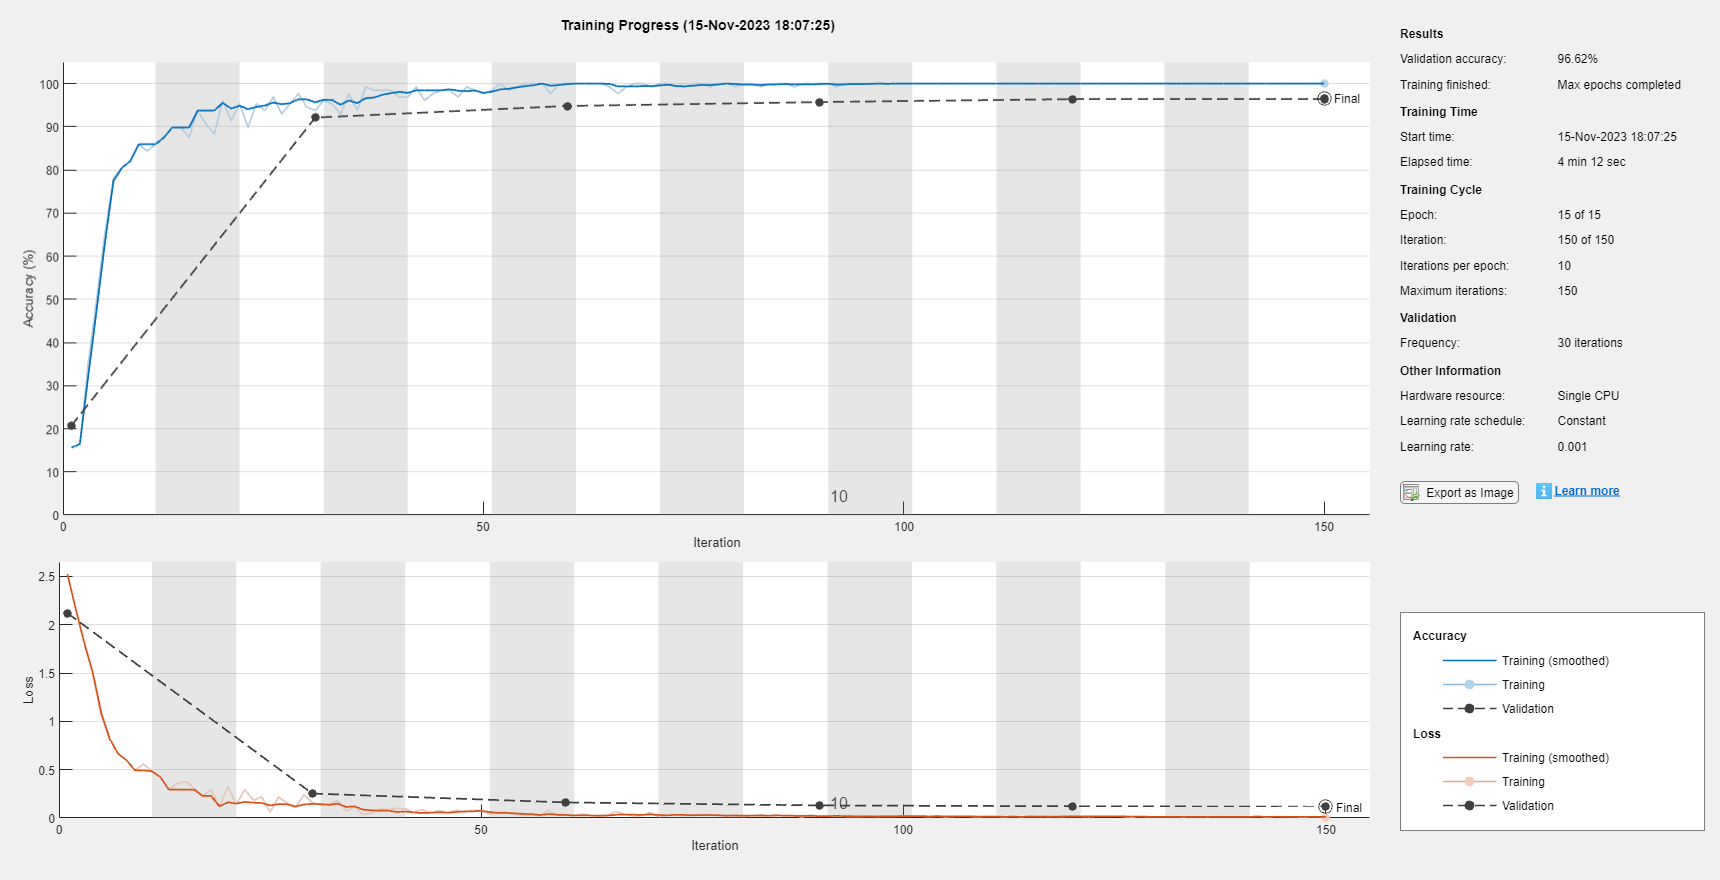

Test Accuracy for 1.000000e-03 Learning Rate: 96.62%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       15.62% |       16.22% |       2.3960 |       2.2997 |      1.0000e-04 |
|       3 |          30 |       00:01:12 |       85.94% |       82.66% |       0.5336 |       0.6228 |      1.0000e-04 |
|       5 |          50 |       00:01:53 |       90.62% |              |       0.4124 |              |      1.0000e-04 |
|       6 |          60 |       00:02:10 |       89.06% |       86.94% |       0.3860 |   

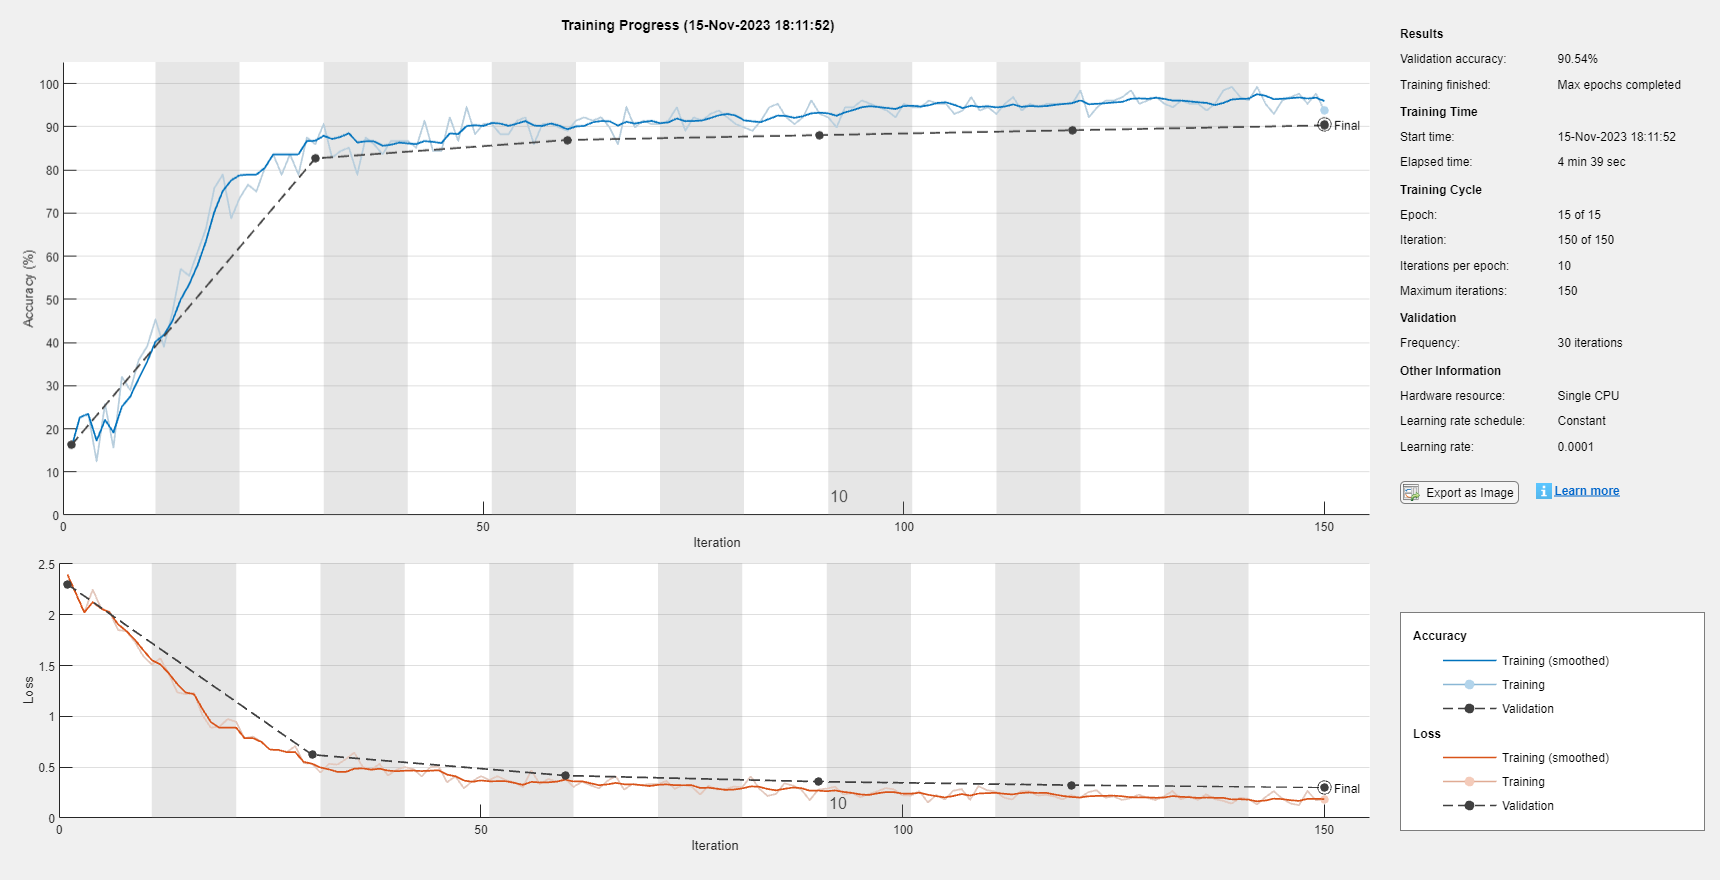

Test Accuracy for 1.000000e-04 Learning Rate: 90.54%


% Hyperparameter tuning for the number of epochs
learningRates = [0.01, 0.001, 0.0001]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
LRaccuracyMatrix = zeros(length(learningRates), 1);
LRTrainingTime = zeros(length(learningRates), 1);

for idx = 1:length(learningRates)
    currentlearningRate = learningRates(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.InitialLearnRate = currentlearningRate;
    options.MaxEpochs = 15;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    LRaccuracyMatrix(idx) = accuracy;
    LRTrainingTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Learning Rate: %.2f%%\n', currentlearningRate, accuracy * 100);
end

% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
figure;

bar(learningRates, LRaccuracyMatrix);

xlabel('Learning Rates');
ylabel('Accuracy');
ylim([0.9, 1]); 

title('Accuracy Performance vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_accuracy.eps'

eps_filename = 'results/learning_rate_accuracy.eps'

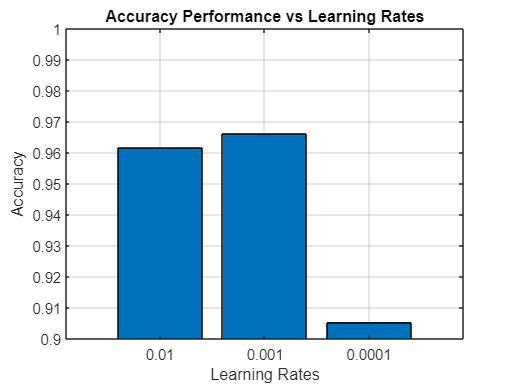

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/learning_rate_accuracy.eps


% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
figure;

bar(learningRates, LRTrainingTime);

xlabel('Learning Rates');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_trainingtime.eps'

eps_filename = 'results/learning_rate_trainingtime.eps'

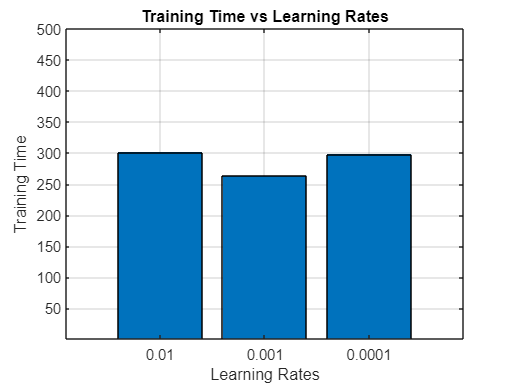

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/learning_rate_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       14.06% |       20.72% |       2.5499 |       3.2615 |          0.0100 |
|       3 |          30 |       00:01:05 |       95.31% |       92.34% |       0.1906 |       0.2627 |          0.0100 |
|       5 |          50 |       00:01:42 |       97.66% |              |       0.0813 |              |          0.0100 |
|       6 |          60 |       00:02:05 |       96.88% |       94.14% |       0.1449 |   

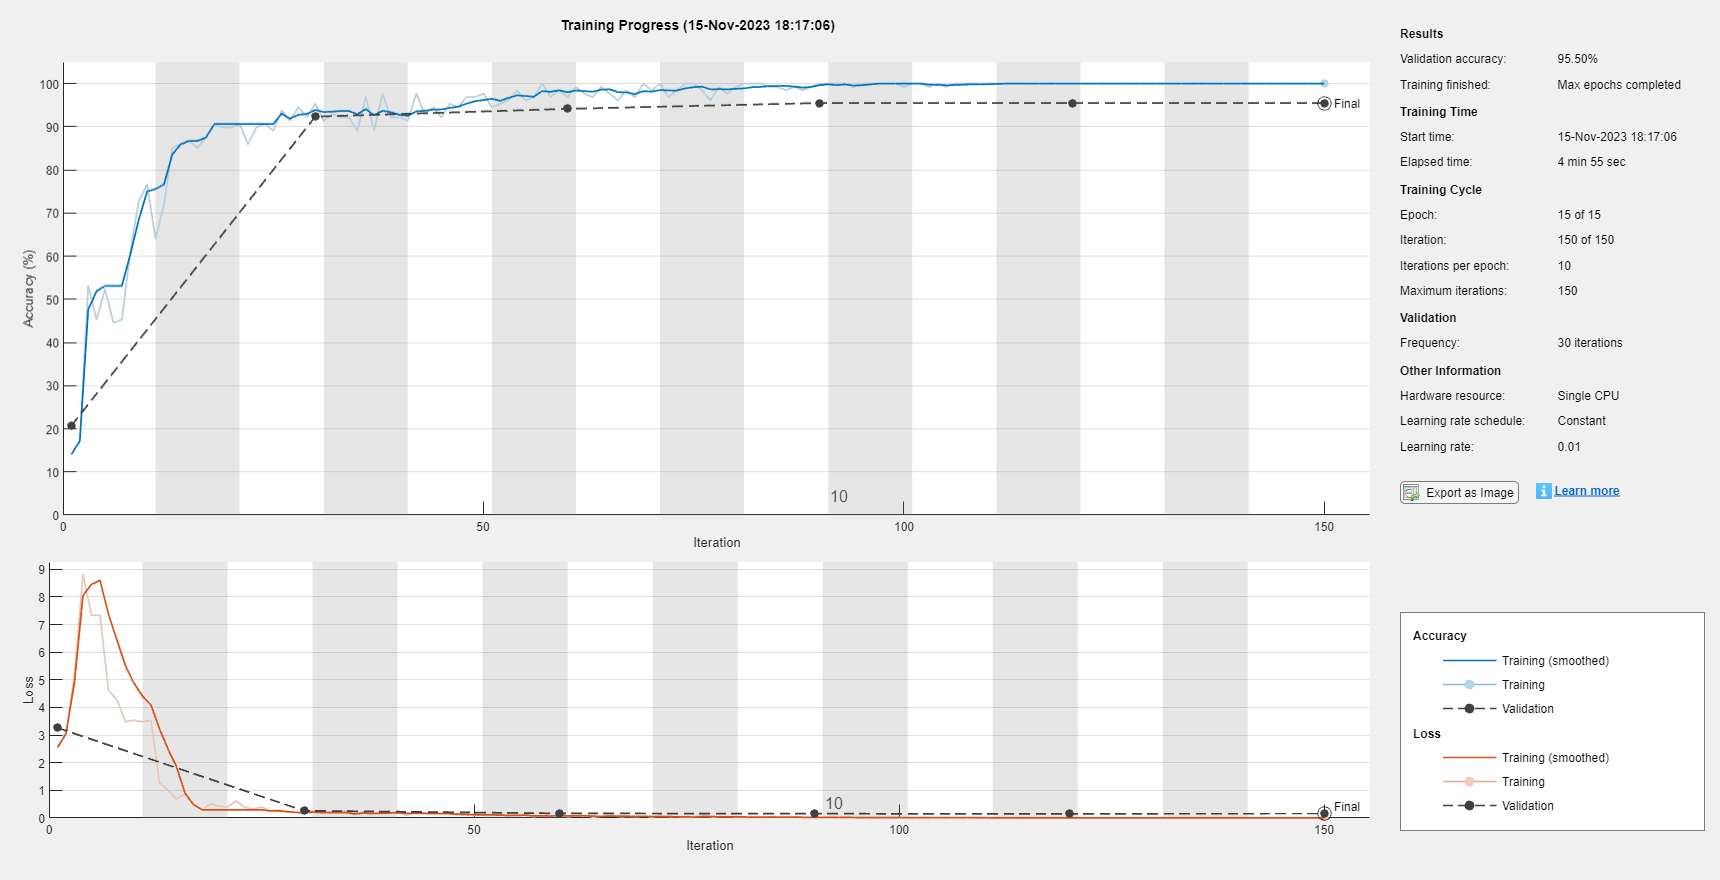

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       14.84% |       43.69% |       2.3926 |      47.7013 |          0.0100 |
|       3 |          30 |       00:00:44 |       96.88% |       92.34% |       0.0862 |       0.8852 |          0.0100 |
|       5 |          50 |       00:01:16 |       99.22% |              |       0.0404 |              |          0.0100 |
|       6 |          60 |       00:01:30 |      100.00% |       95.72% |       0.0017 |   

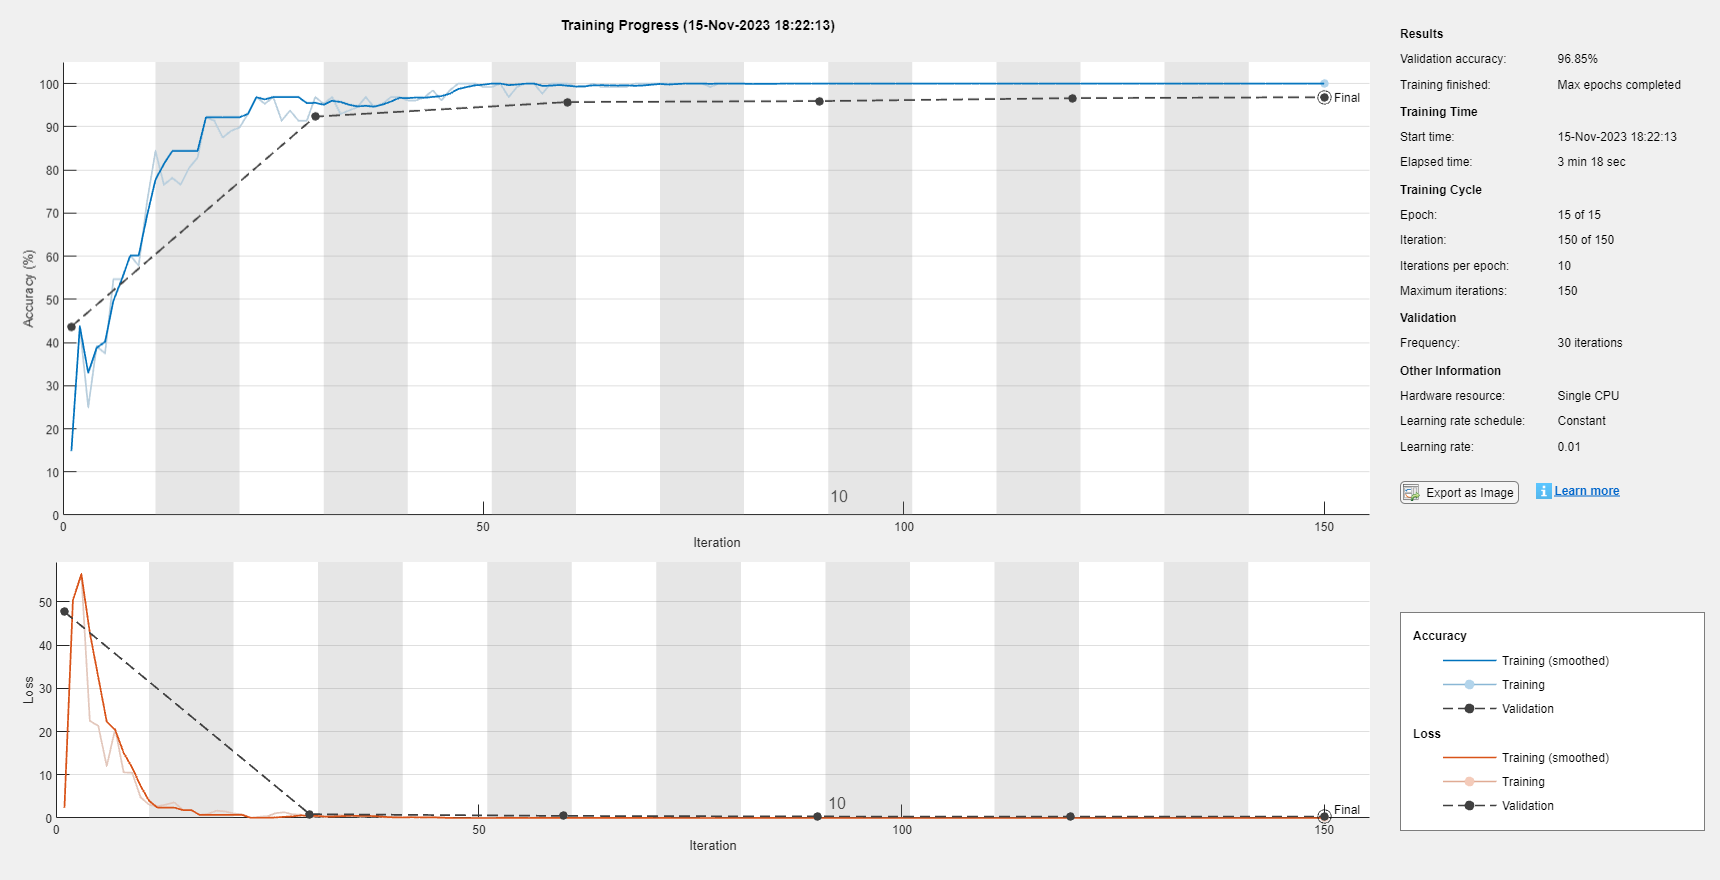

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       14.06% |       25.00% |       3.0534 |     129.6394 |          0.0100 |
|       3 |          30 |       00:00:39 |       82.03% |       83.56% |       6.5527 |       2.3990 |          0.0100 |
|       5 |          50 |       00:01:03 |       93.75% |              |       0.9614 |              |          0.0100 |
|       6 |          60 |       00:01:16 |       98.44% |       95.50% |       0.0677 |   

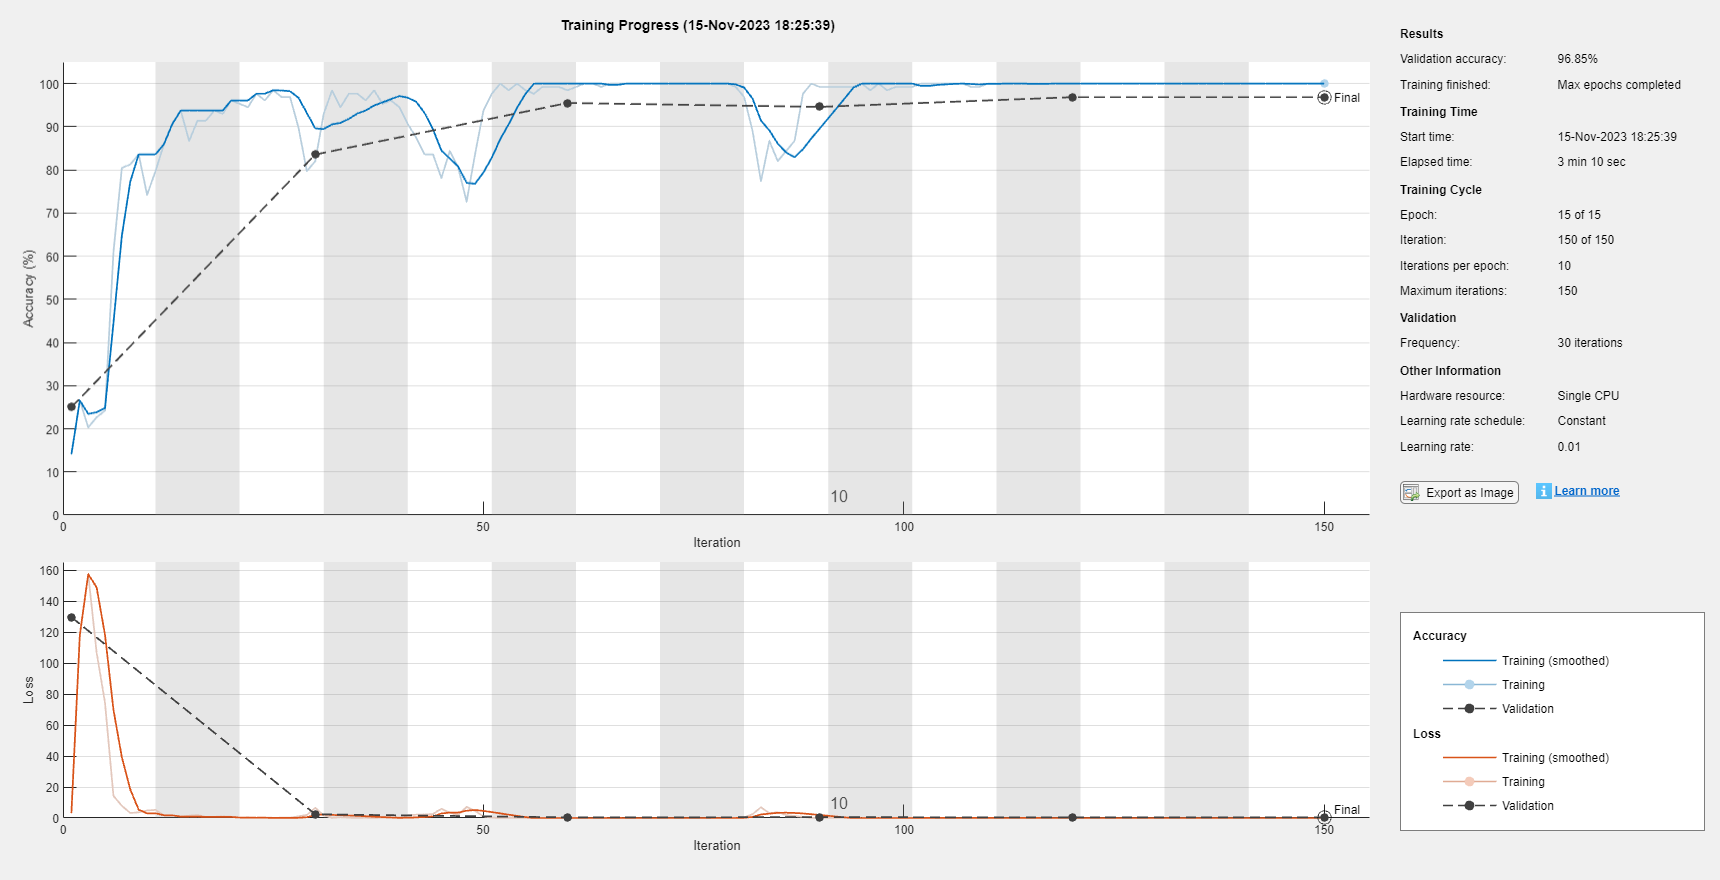


% Hyperparameter tuning for the number of epochs
optimizers = {'sgdm', 'adam', 'rmsprop'}; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
OaccuracyMatrix = zeros(length(optimizers), 1);
OTrainingTime = zeros(length(optimizers), 1);

for idx = 1:length(optimizers)
    currentoptimizer = optimizers(idx);

    options = trainingOptions( ...
    currentoptimizer, ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    OaccuracyMatrix(idx) = accuracy;
    OTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

% Plot the accuracy performance
figure;
bar(optimizers, OaccuracyMatrix);
xlabel('Optimizers');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser.eps'

eps_filename = 'results/optimiser.eps'

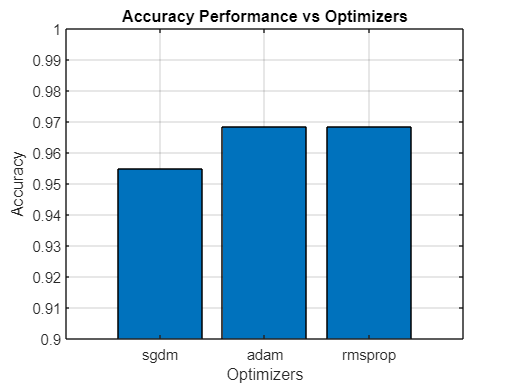

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/optimiser.eps


% Plot the training time
figure;

bar(optimizers, OTrainingTime);

xlabel('Optimizers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser_trainingtime.eps'

eps_filename = 'results/optimiser_trainingtime.eps'

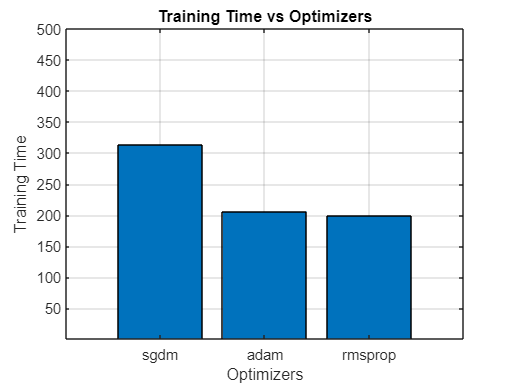

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/optimiser_trainingtime.eps


% Hyperparameter tuning for the number of epochs
batch_size = [8,16,32]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
batchaccuracyMatrix = zeros(length(batch_size), 1);
batchTrainingTime = zeros(length(batch_size), 1);

for idx = 1:length(batch_size)
    currentbatch_size = batch_size(idx);

    options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'MiniBatchSize', currentbatch_size, ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    batchaccuracyMatrix(idx) = accuracy;
    batchTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:10 |        0.00% |       22.30% |       3.2278 |       7.6535 |          0.0100 |


|       1 |          30 |       00:00:22 |       12.50% |       14.19% |       1.9354 |       1.9468 |          0.0100 |


|       1 |          50 |       00:00:24 |        0.00% |              |       1.9687 |              |          0.0100 |


|       1 |          60 |       00:00:27 |        0.00% |       14.41% |       1.9841 |       1.9481 |          0.0100 |


|       1 |          90 |       00:00:34 |       12.50% |       14.19% |       1.9631 |       1.9470 |          0.0100 |


|       1 |         100 |       00:00:36 |        0.00% |              |       1.9738 |              |          0.0100 |


|       1 |         120 |       00:00:39 |        0.00% |       14.19% |       1.9737 |       1.9475 |          0.0100 |


|       1 |         150 |       00:00:45 |        0.00% |       14.19% |       1.9968 |       1.9503 |          0.0100 |


|       2 |         180 |       00:00:49 |       25.00% |       14.19% |       1.9437 |       1.9478 |          0.0100 |


|       2 |         200 |       00:00:51 |       37.50% |              |       1.9346 |              |          0.0100 |


|       2 |         210 |       00:00:54 |       12.50% |       14.19% |       1.9481 |       1.9486 |          0.0100 |


|       2 |         240 |       00:00:58 |       12.50% |       14.19% |       1.9412 |       1.9480 |          0.0100 |


|       2 |         250 |       00:00:59 |        0.00% |              |       1.9679 |              |          0.0100 |


|       2 |         270 |       00:01:02 |        0.00% |       14.41% |       2.0067 |       1.9489 |          0.0100 |


|       2 |         300 |       00:01:10 |       12.50% |       14.19% |       1.9572 |       1.9468 |          0.0100 |


|       2 |         330 |       00:01:18 |       50.00% |       14.41% |       1.9222 |       1.9467 |          0.0100 |


|       3 |         350 |       00:01:21 |       25.00% |              |       1.9315 |              |          0.0100 |


|       3 |         360 |       00:01:23 |        0.00% |       14.41% |       1.9376 |       1.9467 |          0.0100 |


|       3 |         390 |       00:01:31 |       12.50% |       14.41% |       1.9681 |       1.9471 |          0.0100 |


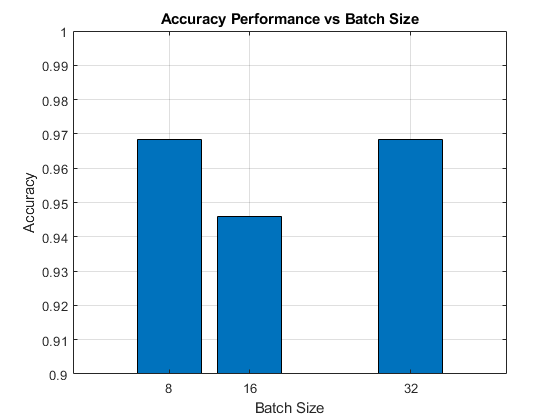

% Plot the accuracy performance
batch_size = [8,16,32];
figure;
bar(batch_size, batchaccuracyMatrix);
xlabel('Batch Size');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batchsize.eps';
saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/batchsize.eps


% Plot the training time
figure;
bar(batch_size, batchTrainingTime);

xlabel('Batch Size');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batch_size_trainingtime.eps'

eps_filename = 'results/batch_size_trainingtime.eps'

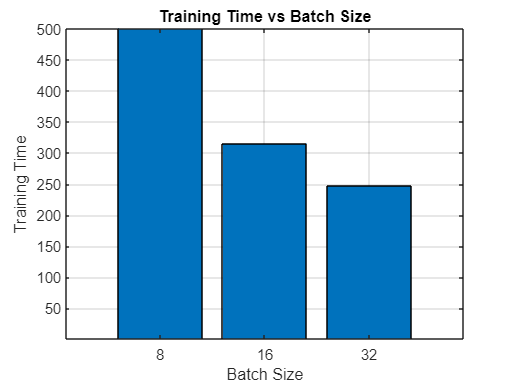

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/batch_size_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       17.97% |       45.50% |       2.4157 |       4.1621 |          0.0100 |
|       3 |          30 |       00:01:34 |       94.53% |       93.02% |       0.1212 |       0.1818 |          0.0100 |
|       5 |          50 |       00:02:19 |       99.22% |              |       0.0239 |              |          0.0100 |
|       6 |          60 |       00:02:46 |      100.00% |       96.17% |       0.0012 |   

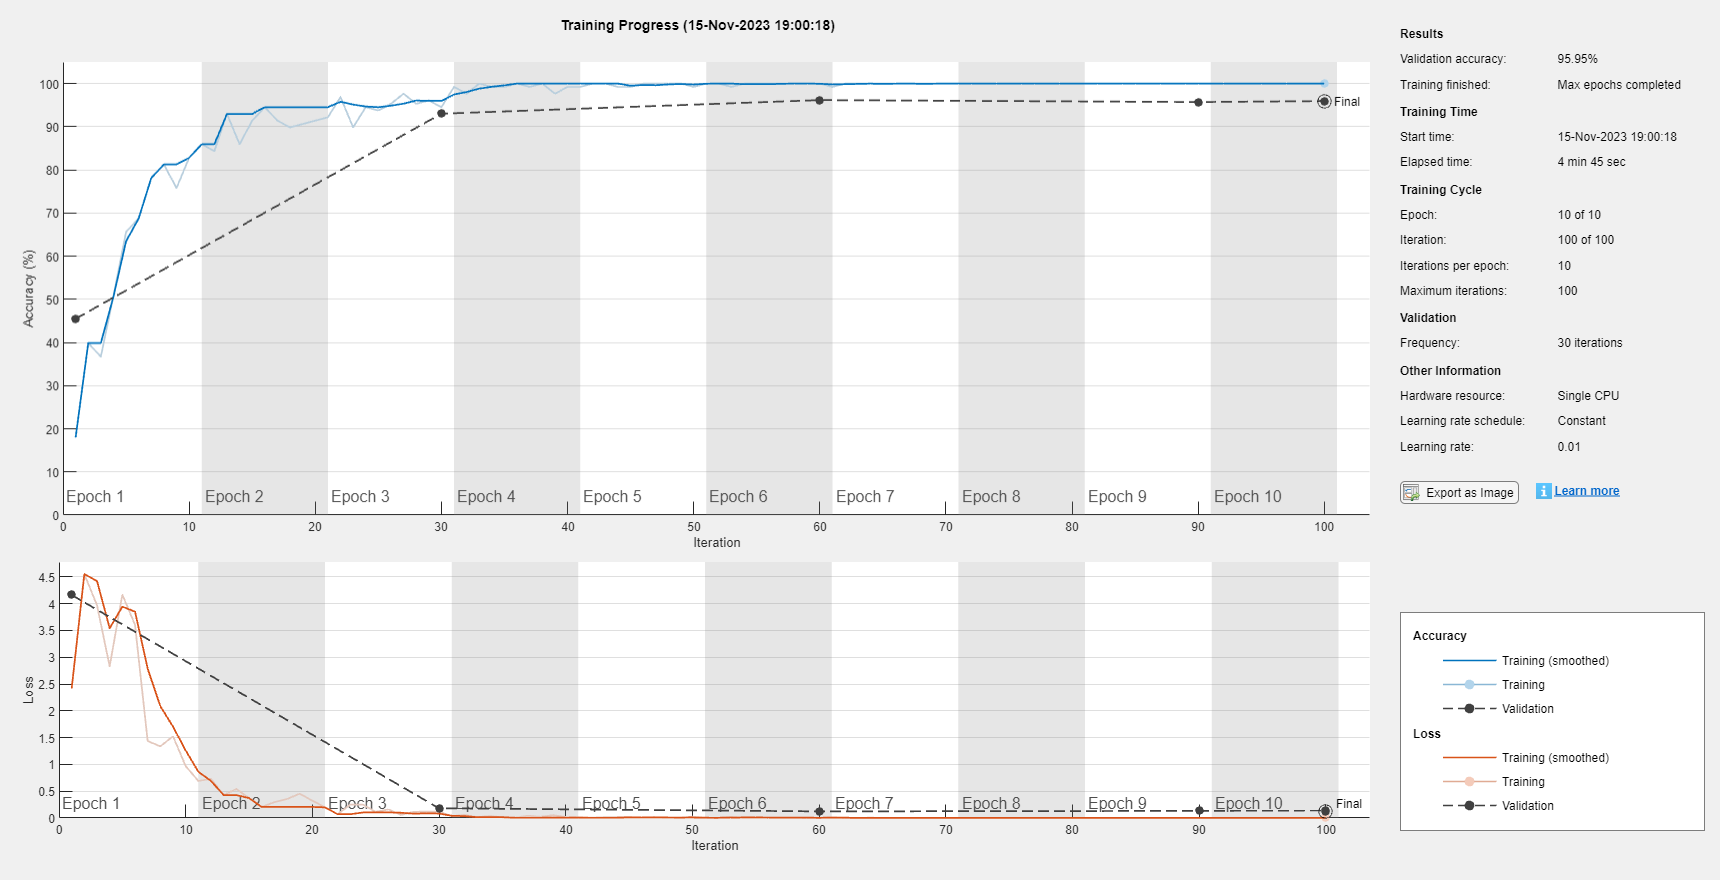

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |        7.81% |       20.95% |       2.9701 |       3.2176 |          0.0100 |
|       3 |          30 |       00:01:34 |       94.53% |       93.02% |       0.1634 |       0.2526 |          0.0100 |
|       5 |          50 |       00:03:04 |       99.22% |              |       0.0498 |              |          0.0100 |
|       6 |          60 |       00:03:43 |      100.00% |       96.62% |       0.0227 |   

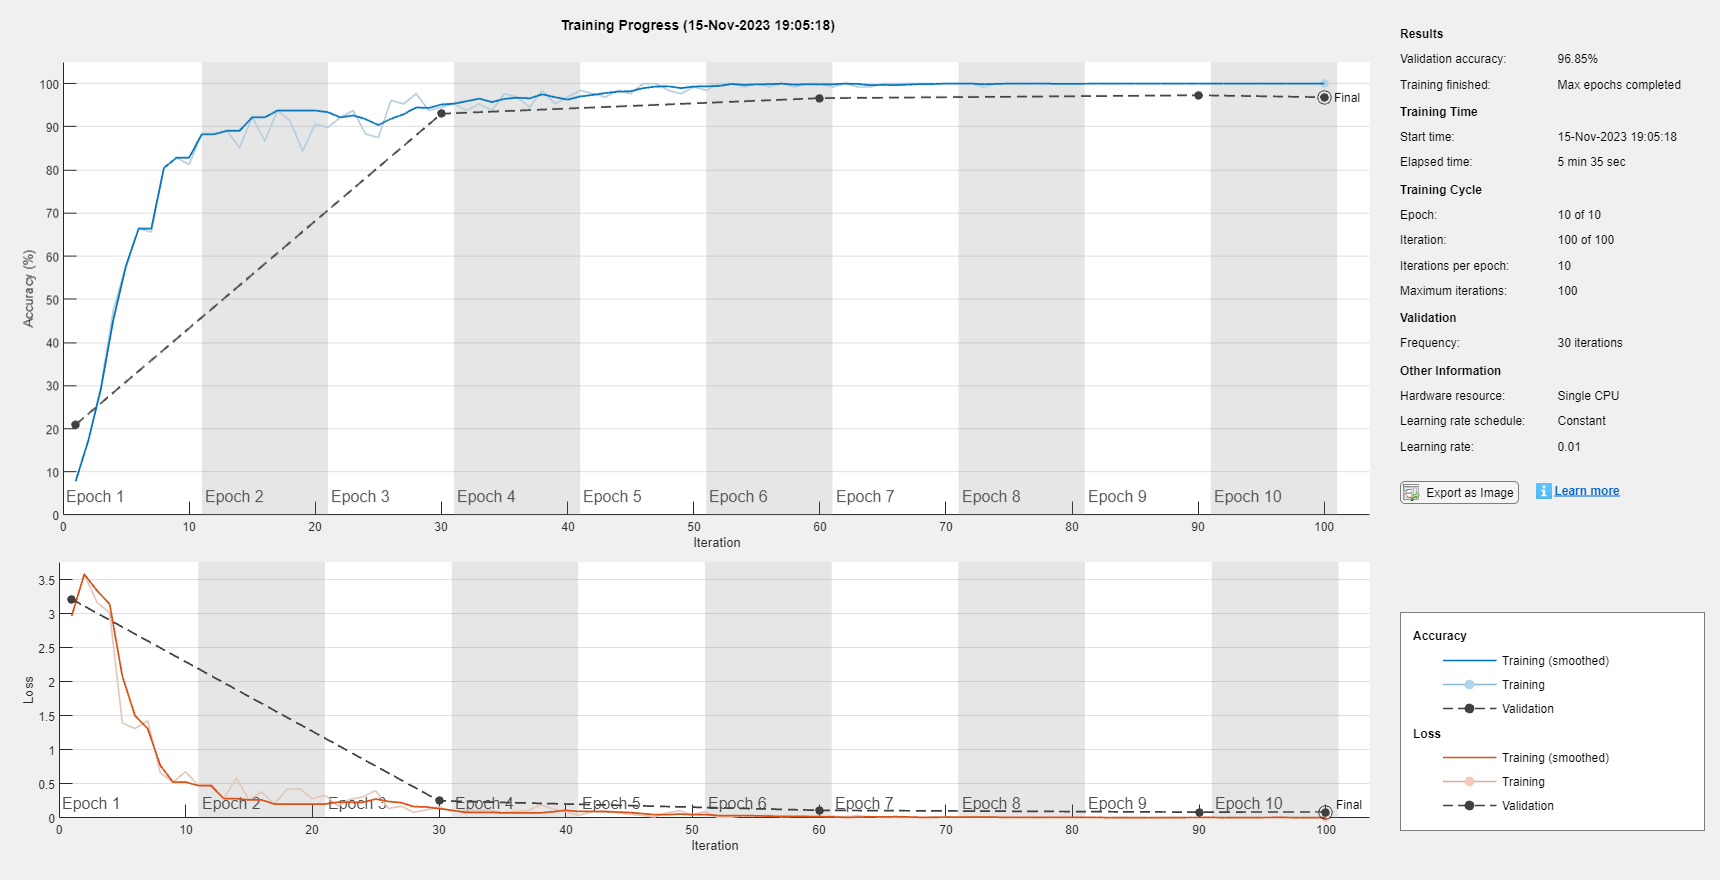

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       15.62% |       20.72% |       2.9506 |       2.2986 |          0.0100 |
|       3 |          30 |       00:01:21 |       97.66% |       93.92% |       0.0826 |       0.1834 |          0.0100 |
|       5 |          50 |       00:02:15 |       97.66% |              |       0.0939 |              |          0.0100 |
|       6 |          60 |       00:02:47 |      100.00% |       97.30% |       0.0444 |   

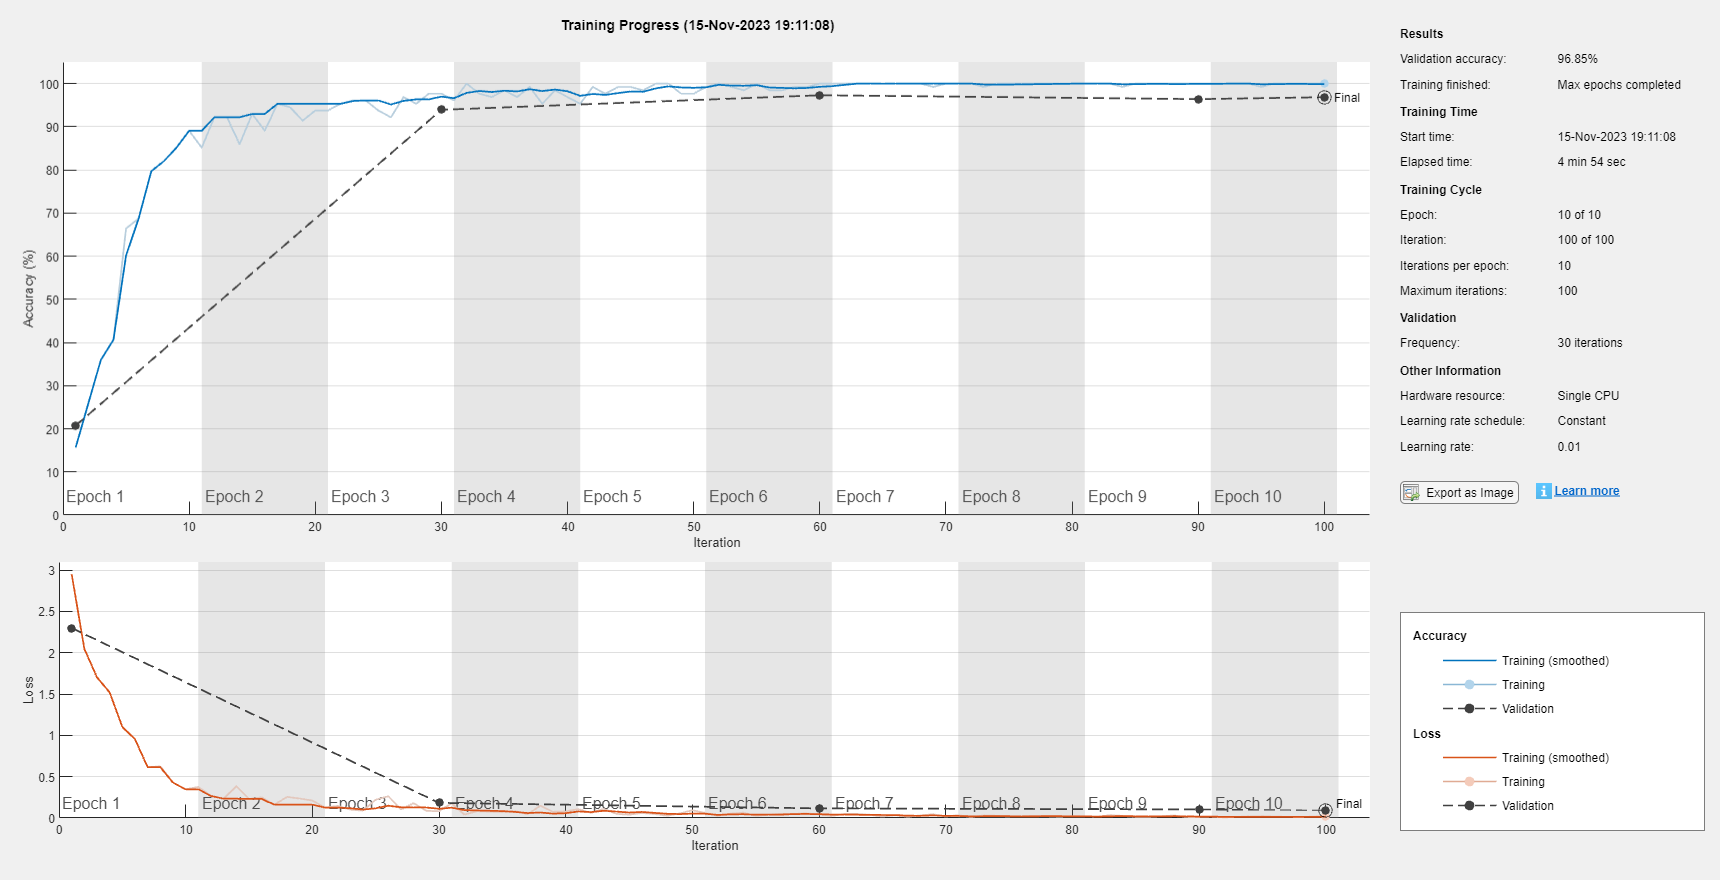

% Constants
numConvLayersList = [2, 3, 4]; % Vary the number of convolution layers
numConfigs = numel(numConvLayersList);
LayersaccuracyResults = zeros(numConfigs, 1);
LayersTrainingTime = zeros(numConfigs, 1);

% Loop through different configurations
for i = 1:numConfigs
    % Define the neural network architecture with varying convolution layers
    layers = [
        imageInputLayer([imageSize 1])
    ];
    
    for j = 1:numConvLayersList(i)
        layers = [layers
            convolution2dLayer(3, 16, 'Padding', 'same')
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
        ];
    end
    
    layers = [layers
        fullyConnectedLayer(numel(categories))
        softmaxLayer
        classificationLayer
    ];

    % Set training options
    options = trainingOptions( ...
        'sgdm', ... % Stochastic Gradient Descent with Momentum
        'InitialLearnRate', 0.01, ...
        'MaxEpochs', 10, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', {testImages, testLabels}, ...
        'ValidationFrequency', 30, ...
        'Verbose', true, ...
        'Plots', 'training-progress' ...
        );

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    
    % Store the accuracy for this configuration
    LayersaccuracyResults(i) = accuracy;
    LayersTrainingTime(i) = trainingTime;
end

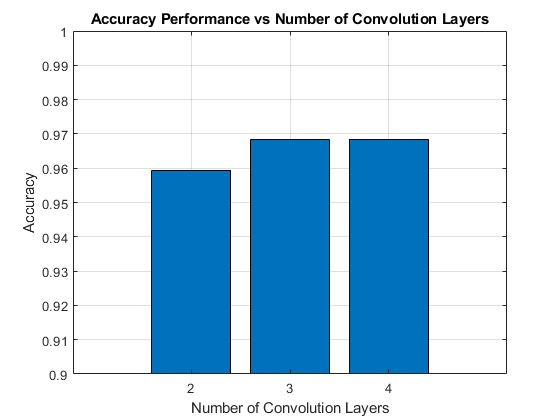

% Plot the results
figure;
bar(numConvLayersList, LayersaccuracyResults)
xlabel('Number of Convolution Layers')
ylabel('Accuracy')
ylim([0.9, 1]); 
title('Accuracy Performance vs Number of Convolution Layers')
grid on;


% Save the plot as an EPS file
eps_filename = 'results/layers.eps'

eps_filename = 'results/layers.eps'

saveas(gcf, eps_filename, 'epsc');

Error using saveas (line 138)
Invalid or missing path: results/layers.eps

fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;
bar(numConvLayersList, LayersTrainingTime);

xlabel('Number of Convolution Layers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Convolution Layers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/layers_trainingtime.eps'

eps_filename = 'results/layers_trainingtime.eps'

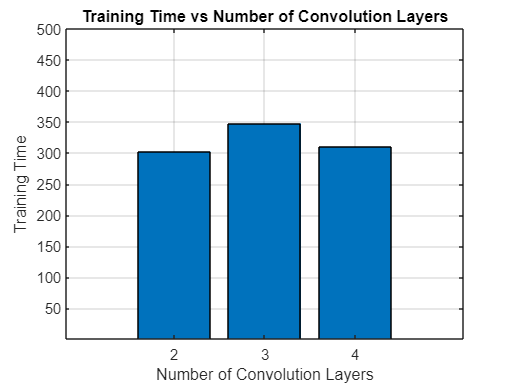

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/layers_trainingtime.eps
